This is a summary of key findings and changes during model development, in

roughly chronological order.

- Some basic operations were done in for loops rather than as vectors.  I made the changes, speeding up the code by 10x or more.  This will mean less waiting during testing.

- The GUI is nice, but slow compare to just running code.  I made a simple script to bypass the GUI, with the intent or restoring it later.

- Side note: building a "mex" executable could be a big speed (and possibly memory) win if simulations become large and slow.

## Random walk bias

I noticed that the random walk was either 1 unit up or down, when it seems that a continuous distribution might make more sense.  The first paper I found (Visser 1997) points out a common error which leads to biased migration of particles toward areas of low diffusion.  We have that problem!  Running with a drop in diffusivity by a factor of 4 at 50 meters, this uneven distribution is obtained after 4 hours:

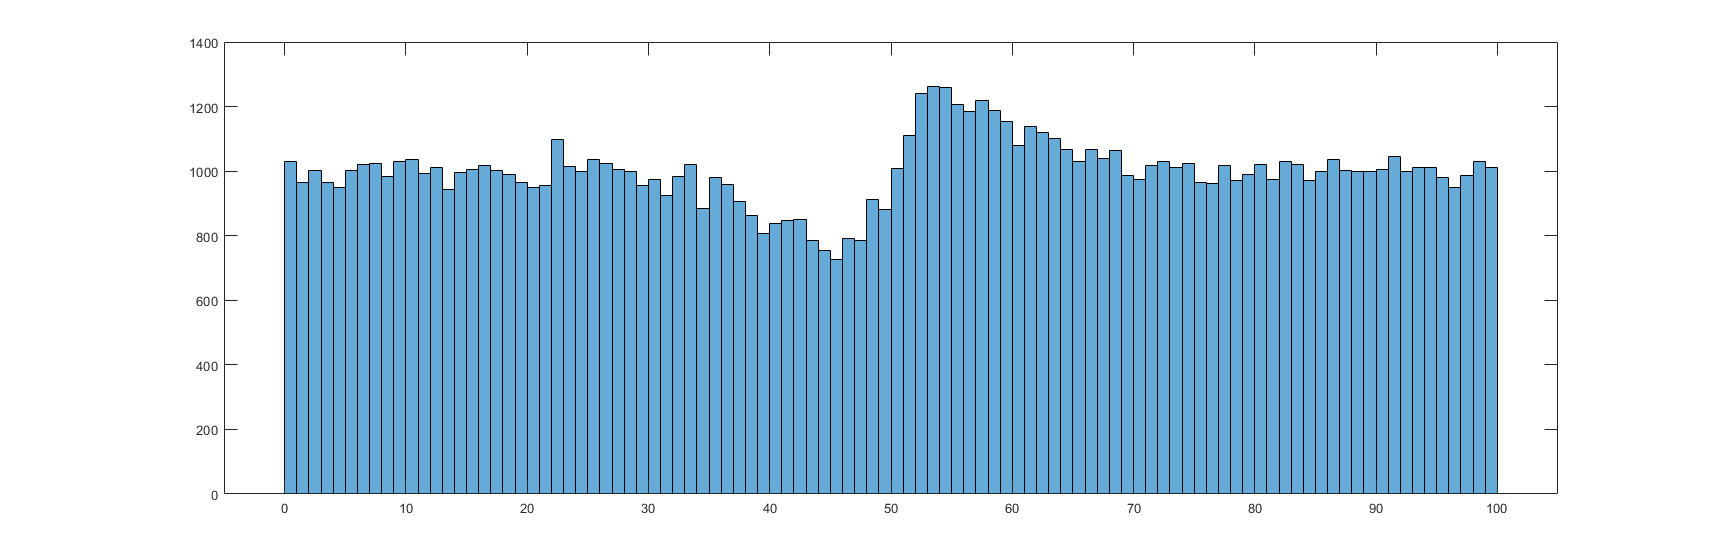

openfig('Biased_Diffusion.fig');

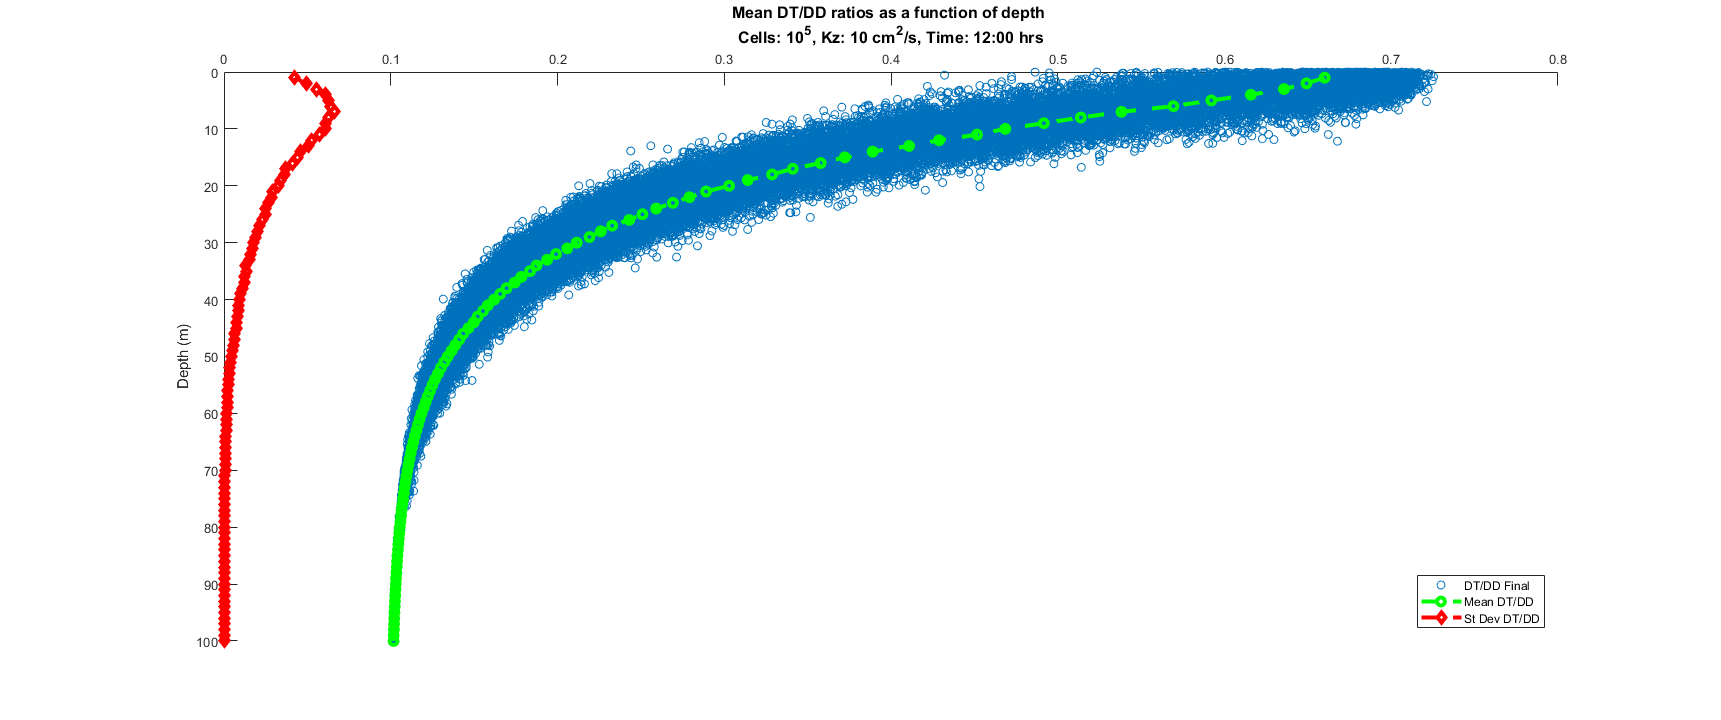

openfig('Biased_DTDD.fig');

The function in the original version uses the code 

`sqrt(2*dt*Kz)`

Representing a step size of

 $\pm \sqrt{2K\delta t}$  where the sign is chosen randomly.

Visser (1997) equation 3 shows

$R\sqrt{\frac{2}{r}K\delta t}$  where R is random and r is the standard deviation of R.

however Visser points out that this leads to a bias when K is not constant, recommending (equation 6)

$\mathrm{K'}\left(z\right)\delta t+R\sqrt{\left\lbrace \frac{2}{r}K\left\lbrack z+\frac{1}{2}\mathrm{K'}\left(z\right)\delta t\right\rbrack \delta t\right\rbrace }$ where $\mathrm{K'}=\frac{\delta K}{\delta z}$

BUT the square brackets are meant to imply that K is a function of the contents, not normal mathematical grouping!

Examples in the paper use a uniform distribution from -1 to 1 for R, not a normal distribution, so I will do the same.  The standard deviation is then $\sqrt{\frac{1}{3}}$.

The figures above are repeated below with the new approach.  Note that particles are no longer "pumped" from high to low diffusion areas.  Run time increases from 2.31 to 4.13 seconds for n=5, due to the extra interpolations.  **Note** that the effective diffusion rate is lower since step sizes range between 0 and 0.4558, as opposed to being fixed at 0.3464 in the original code.

# **ERROR: there was a coding error which produced the result below!  Now the pumping is as bad or worse!  It may have to do with time steps, since the calculated offsets are big enough to put all particles outside of the area where the K slope is not zero.  SOLVE THIS!**

I considered the condition specified in Visser (1997) that dt << min(1/K'').  Again, his notation escapes me, because K'' includes values close to zero and can be of either sign.  Another paper, North (2006) quotes this expression exactly, and reports no trouble using it as give.  If I arbitrarily use absolute values and  ignore values lower than 0.001, I get a value of** 0.0278**, which suggests that our timestep of 60 (seconds) is much too small.  The value may be larger or smaller with a realistic diffusion profile - the current one is an arbitrary guess for testing.

I tried reducing the time step to 6 and the 0.6.  This greatly reduced the unevenness of the distribution, but also sharply reduce the diffusion.  This is clearly wrong.  Is something hardcoded which cause a smaller timestep to simulate less time???  Yes - after a couple of bug fixes I was able to run correctly with a step size of 6.  This greatly decreased the distribution error with no obvious change to the width of the overall distribution (which is good).  A step size of 0.6 means asking Matlab for a 100000x72000 array (53.6 GB) which is cleverly refuses to do. Do we really need to store all that?

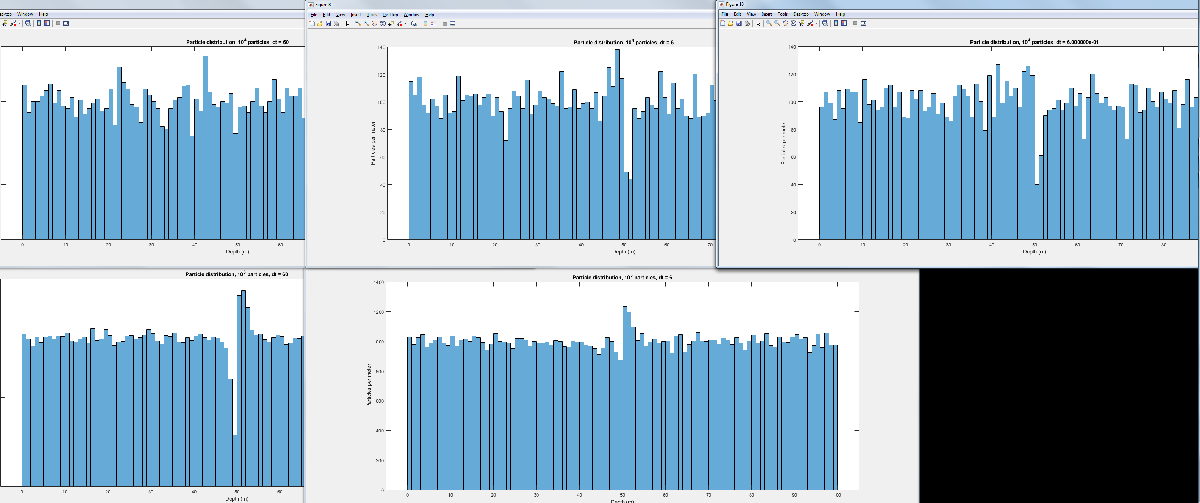

These figures represent particle distribution after 12 hours with various combinations of n and dt.  

## Solution to the need for a smaller time step

TODO: We need (check this!) a time history to figure out the accumulated daitoxanthin to diadinoxanthin ratios.  Since small time steps make the array too large, keep values at the original 60 second intervals, but compute more finely between those points.  It this proves to be really slow, it might pay to identify areas of large 2nd derivative and compute only those areas with a fine time step.  For example, only the top and bottom of the thermocline are likely to need the finest time steps.  Also note that in early testing, the 2nd derivative is a function of the number of particles because that changes the z step size.  This should not be true of a realistic distribution.

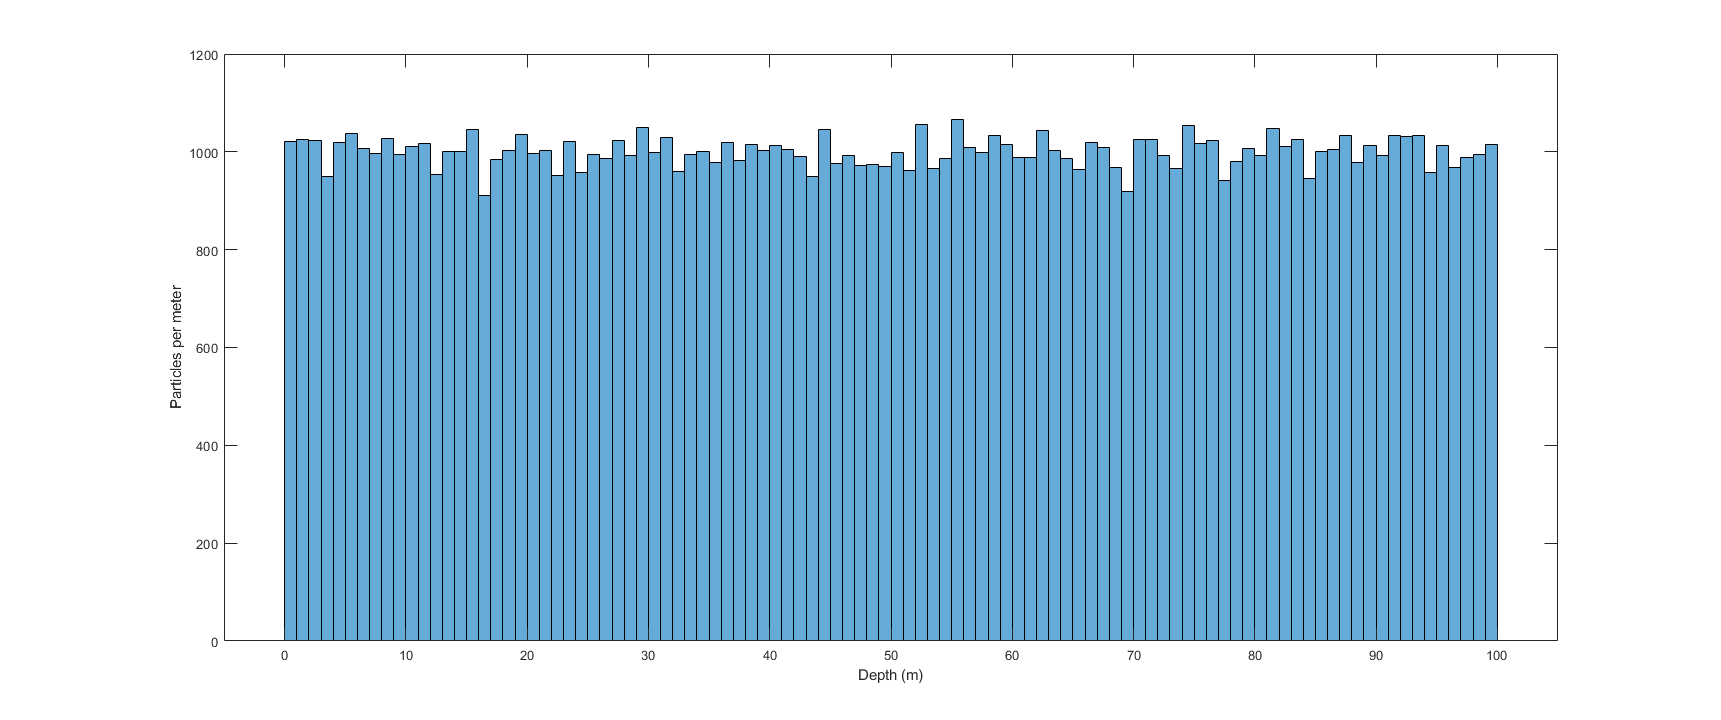

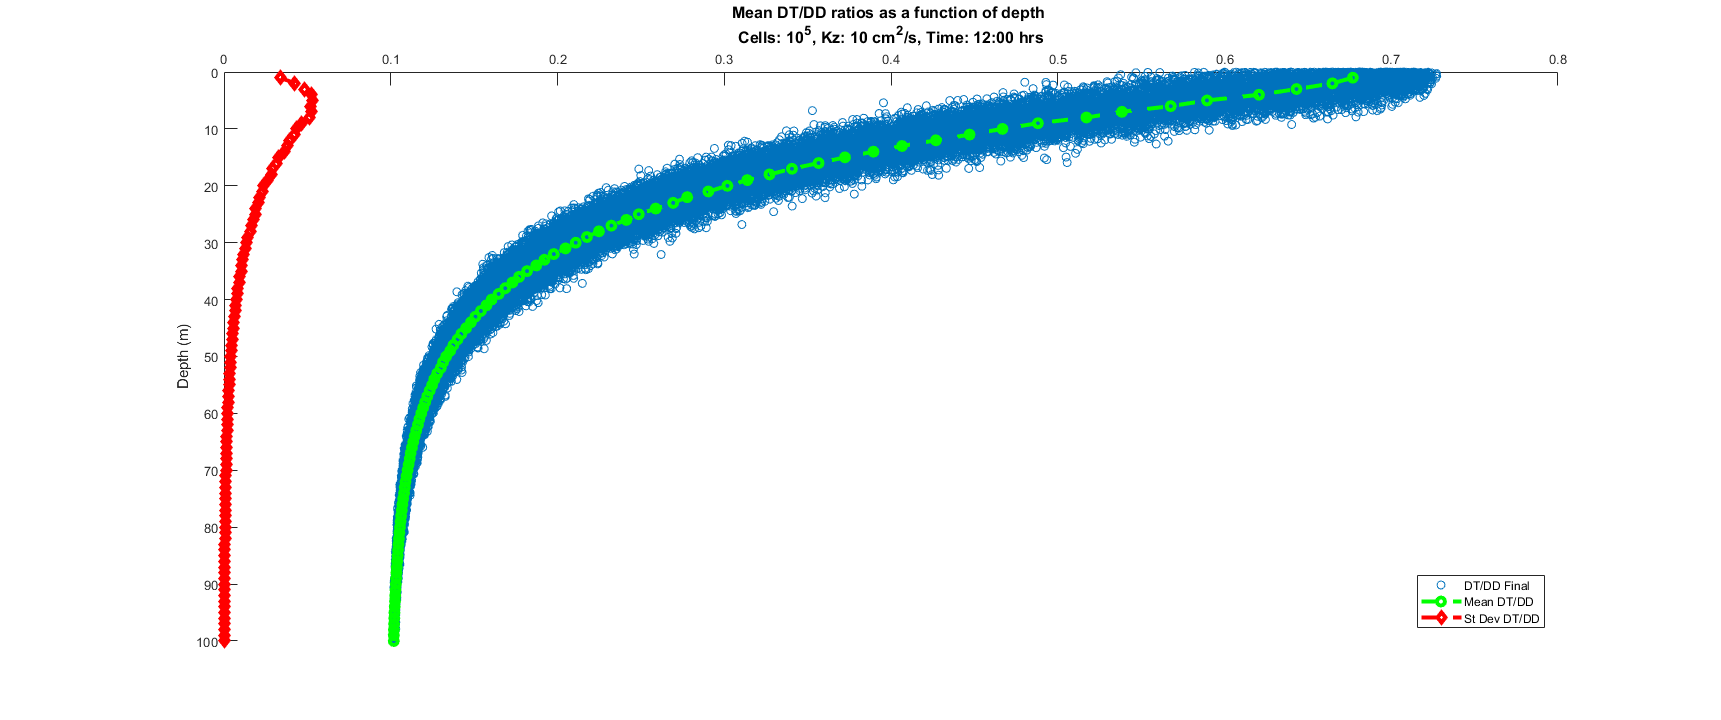

openfig('Diffusion_VisserEq6.fig'); openfig('DTDD_VisserEq6.fig');

## Adding the Thermocline

## References

North, E. W., Hood, R. R., Chao, S. Y. & Sanford, L. P. Using a random displacement model to simulate turbulent particle motion in a baroclinic frontal zone: A new implementation scheme and model performance tests. *J. Mar. Syst.* **60,** 365–380 (2006).

Visser, A. Using random walk models to simulate the vertical distribution of particles in a turbulent water column. *Mar. Ecol. Prog. Ser.* **158,** 275–281 (1997).